# cleaning

clc;
clear variables;
close all;

## Reading Audio

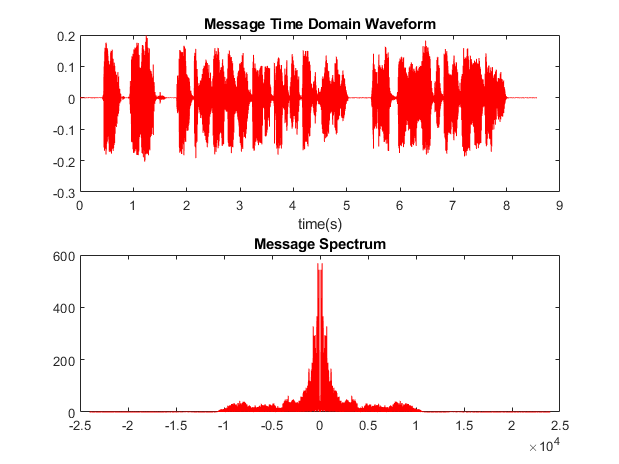

% read the audio file 
[message , FS] = audioread ('eric.wav') ;

%sound time domain plot
timeAxis = linspace(0, length(message)/FS , length(message)) ;
figure
subplot(2,1,1)
plot (timeAxis , message,'r'); xlabel('time(s)') ; title('Message Time Domain Waveform');
%message spectrum plot
Fdom1 = linspace(-FS/2 , FS/2 , length(message));
message_freq_domain = fftshift(fft(message)) ;
message_mag = abs(message_freq_domain) ;
subplot(2,1,2); 
plot (Fdom1, message_mag,'r') ; title('Message Spectrum');


% play the audio file
% sound (message , FS) ;


## Filtering

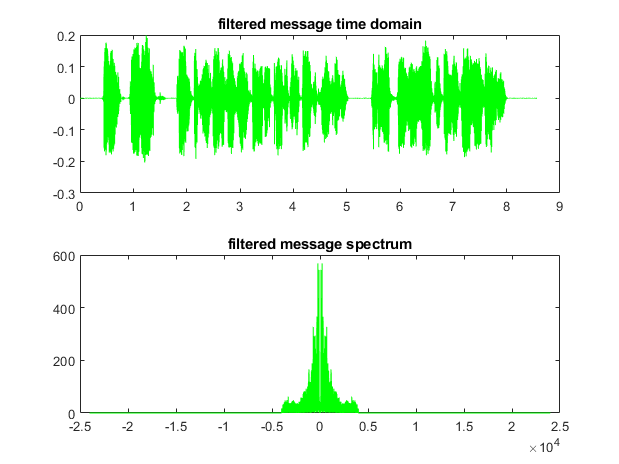

n = FS/(length(message)-1) ;
% first interval
freq1 = -FS/2 : n : -4000 ;
mag1 = zeros(1, length(freq1)) ;
% second interval
freq2 = -4000: n : 4000 ;
mag2 = ones(1, length(freq2)) ;
% third interval
freq3 = 4000 : n : FS/2 ;
mag3 = zeros(1, length(freq3));
% filtering 
filter = [mag1 mag2 mag3];
filtered_message_F = filter' .* message_mag ;

% converting from frequency domain to time domain 
size(filtered_message_F); size(message) ;
filtered_message_T = real(ifft(ifftshift(message_freq_domain))) ;

% PLOTTING
figure
subplot(2,1,2);
plot(Fdom1 , filtered_message_F,'g') ; title('filtered message spectrum'); 
subplot(2,1,1);
plot(timeAxis , filtered_message_T,'g'); title('filtered message time domain') ;


% playing audio
% sound(filtered_message_T , FS)


## NBFM Modulation

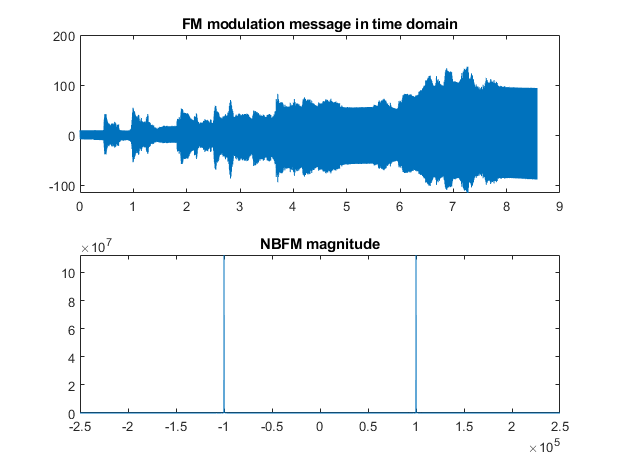

% Modulation equation
%   s(t) = A cos(2 pi Fc t) - A Kf sin(2 pi Fc t) integration(message)

Fc = 100000;                % carrier frequency
FS2 = 5 * Fc;               % sampling frequency
Kf = 2 * pi * 0.01;         % frequency Sensitivity
A = 10;                     % carrier amplitude

% resampling the message
message_resampled = resample(filtered_message_T , FS2 , FS);

% generating linspaces
t = linspace (0 ,  (length(message_resampled)) / FS2 , length(message_resampled)) ;
Fdom2 = linspace( (-FS2)/2 , FS2/2 , length(message_resampled) ) ;

%figure; plot(t, message_resampled);

% generating the signal
NBFM_signal = A * cos(2*pi*Fc* t)' - A * Kf * sin(2*pi*Fc* t)' .* cumsum(message_resampled);

NBFM_signal_spectrum = fftshift ( fft (NBFM_signal)) ;

% plots
figure
subplot(2,1,1);
plot ( t,NBFM_signal); title('FM modulation message in time domain');
subplot(2,1,2);
plot(Fdom2, abs(NBFM_signal_spectrum)); title('NBFM magnitude');

## Demodulation

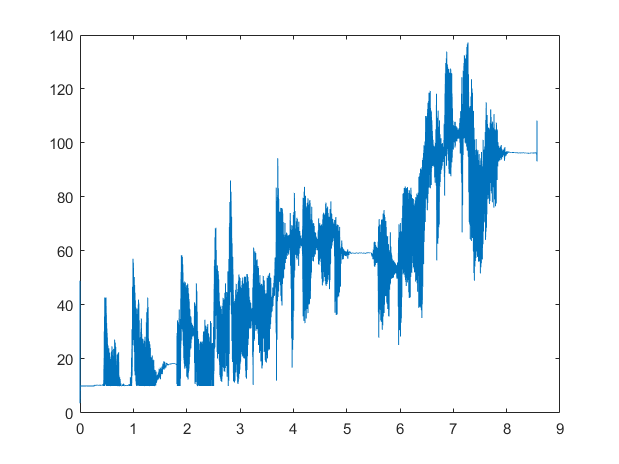

% demodulation is achieved by using an edge detector 
% followed by a differentiator

% envelope detector
out2 = abs(hilbert(NBFM_signal));

figure
plot(t, out2)

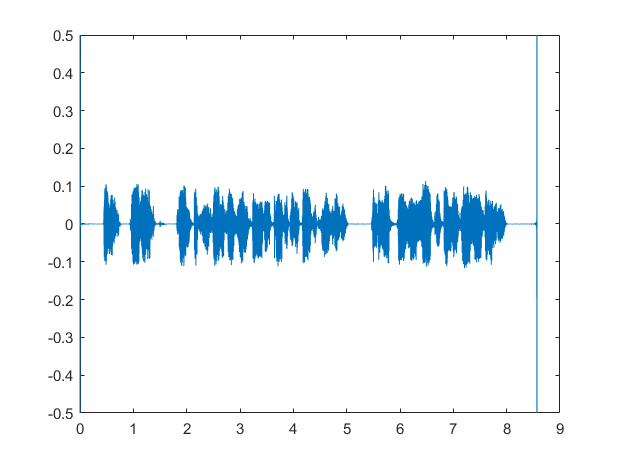

% differentiator
out1 = [0; diff(out2)];

figure
plot(t, out1)
ylim([-0.5 0.5])

sound(3 * resample(out1 , FS , FS2), FS)